% example of how to load in shape file from arcmap
% copy over the .dbf, .shp, and .shx files

shp = shaperead(['beds.shp']) % load in shapefile

shp = 15×1 struct array with fields:
    Geometry
    BoundingBox
    X
    Y
    Id
    sand0_mud1


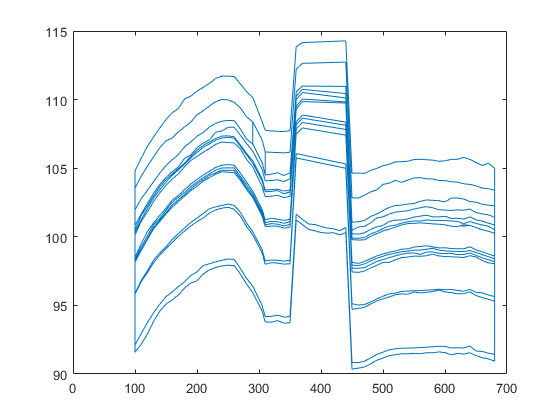

% draw shapes
plot([shp.X], [shp.Y])

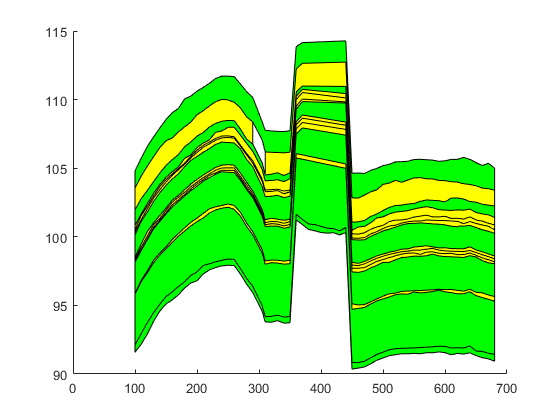

figure; hold on;

% note for chance: change the == 1 to whatever value the mud is.
for i = 1:length(shp)
    if shp(i).sand0_mud1 == 1
        fill([shp(i).X(1:end-1)],[shp(i).Y(1:end-1)],'green')
    else
        fill([shp(i).X(1:end-1)],[shp(i).Y(1:end-1)],'yellow')
    end
end

maxy= 150

maxy = 150

miny= 0

miny = 0

for i=1:length(shp)
    newmaxy = max(shp(i).Y);
    if newmaxy > maxy
        maxy = ceil(newmaxy);
    end
    newminy = min(shp(i).Y);
    if newminy < miny
        miny = floor(newminy);
    end
end

maxx = 700;
minx = 100;
% get the minimum and maximimum dimensions for the entire outcrop to draw a
% verticle line through the outcrop at various intervals
for i=1:length(shp)
    newmaxx = max(shp(i).X);
    if newmaxx > maxx
        maxx = newmaxx;
    end
    newminx = min(shp(i).X);
    if newminx < minx
        minx = newminx;
    end
end
minx = ceil(minx)+.1;
maxx = round(maxx,1);
for i=1:length(shp)
    shp(i).Xspacing = minx:10:maxx;
end

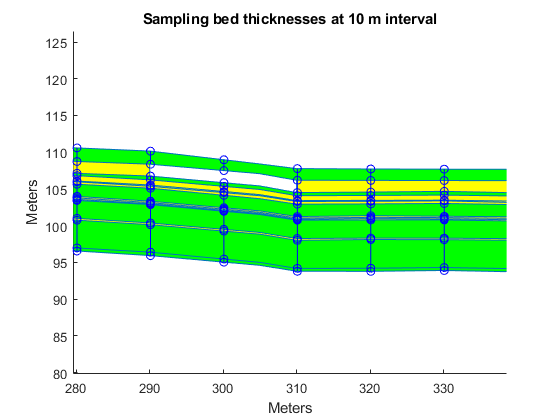

plot([shp.X],[shp.Y])
hold on
% store intersections
% loop through each interval being tested
for j=1:length(shp(1).Xspacing)
    % loop through each bed at that interval
    for i=1:length(shp)
        xi = []; yi = [];
        [xi,yi] = polyxpoly([shp(i).Xspacing(j) shp(i).Xspacing(j)], [miny maxy], [shp(i).X],[shp(i).Y]);
            if isempty(xi) 
                shp(i).yintbase(j) = [NaN]; shp(i).yinttop(j) = [NaN];
            else
                shp(i).yintbase(j) = yi(1);
                shp(i).yinttop(j) = yi(2);
                plot(xi,yi,'o-b')
            end
    end
end
title('Sampling bed thicknesses at 10 m interval')
xlabel('Meters')
ylabel('Meters')
axis equal

xlim([279.6 338.6])
ylim([79.8 126.5])

%calculate thickness at each interval
for i=1:length(shp)
    shp(i).thickness = abs(shp(i).yinttop-shp(i).yintbase);
end
